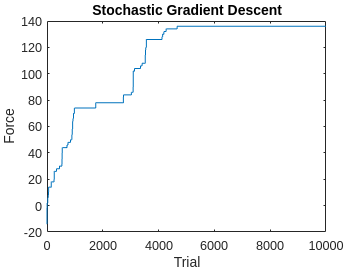

% Creating n Corticalspinal cells
n = 1000;

% Initalize the base CS cells
x_0 = rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor cells
flexor_cs_cells = create_cs(0.7, n);  % Flexor CS cells
extensor_cs_cells = create_cs(0.3, n);  % Extensor CS cells

% Translating MN pool to force
delta = 1;

forces = [];
trials = [];
g = 0.04;  % Learning gain TODO: Aribitrary learning gain for now
f_0 = 0;
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:n
        s_fi = s_fi + g_i(x_i(i), flexor_cs_cells(i));
        % s_fi = s_fi + x_i(i) * c_fi(i);
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:n
        s_ei = s_ei +  g_i(x_i(i), extensor_cs_cells(i));
        % s_ei = s_ei + x_i(i) * c_ei(i);
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    % If it's the first iteration, then there's no past iteration to look
    % at. So continue.
    if trial == 1
        trials = [trial];
        forces = [f_net];

        x_0 = x_i;
        f_0 = f_net;

        continue;
    end

    % Gradient Descent
    x_i_1 = x_i + g * (f_net - f_0) * v_i;
    % Remember the past information
    if f_net > f_0
        x_0 = x_i_1;
        f_0 = f_net;
    end

    trials = [trials, trial];
    forces = [forces, f_0];
end

plot(trials, forces)
title("Stochastic Gradient Descent")
ylabel('Force')
xlabel('Trial')

saveas(gcf,'images/StochasticGradientDescent.png')

Positive saturation limit for excitatory cells (saturation limit is +1) and Negative saturation limit for inhibitory cells (saturation limit is -1)

function s = g_i(c_i, x_i)
    s = -1;
    if c_i * x_i > 0
        s = 1;
    end
end

function c_i = create_cs(percentage, n)
    c_fi_percentage = percentage;
    c_ei_percentage = 1 - percentage;
    % c_fi
    num_of_ones_fi = round(n * (c_fi_percentage/2));
    num_of_zeros_fi = round(n * (c_fi_percentage/2));
    % c_ei
    num_of_neg_ones_ei = round(n * (c_ei_percentage/2));
    num_of_ones_ei = round(n * (c_ei_percentage/2));
    % Create percentage of 1
    c_i = [ones(1, num_of_ones_fi), zeros(1, num_of_zeros_fi), -ones(1, num_of_neg_ones_ei), ones(1, num_of_ones_ei)];
    % c_i shuffle it
    c_i = c_i(randperm(length(c_i)));
end